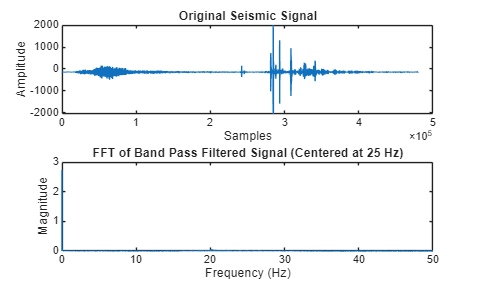

% Load SAC file
sac_file = 'WANC_SHZ_2004_361_01-10-00.SAC';
[data, header] = readsac(sac_file);

% Extract sample period
ts = header.DELTA;
fs = 1/ts;

% Filter Constraints/Info 
taps = 31;
f_pass = fs*0.05;
f_stop = fs*0.1;
f_center = fs*0.25;

% Generate Lowpass Coefficients First
f_norm = [0, f_pass, f_stop, fs/2] / (fs/2);
a = [1, 1, 0, 0];
b = firpm(taps, f_norm, a);

% Band Pass
n_taps = 0:taps;
omega_c = 2*pi*(f_center / fs);
h_bp = 2 * b .* cos(omega_c * n_taps);

% 1. Apply the filter to the original data
filtered_data = filter(h_bp, 1, data);

% FFT of the filtered signal
N_filtered = length(filtered_data);
data_fft_filtered = fft(filtered_data);
mag_filtered = abs(data_fft_filtered / N_filtered);
freq_axis = (0:N_filtered-1) * (fs / N_filtered); 

% Plot results
figure;
subplot(2,1,1);
plot(data); 
title('Original Seismic Signal');
xlabel('Samples'); 
ylabel('Amplitude');

subplot(2,1,2);
plot(freq_axis, mag_filtered);
title(['FFT of Band Pass Filtered Signal (Centered at ', num2str(f_center), ' Hz)']);
xlabel('Frequency (Hz)'); 
ylabel('Magnitude');
xlim([0 fs/2]);